# Two-Link Planar Manipulator PSDM Example

This example shows how PSDM can be used to derive the regressor for of the dynamics of motion of a simple two-link planar manipulator.

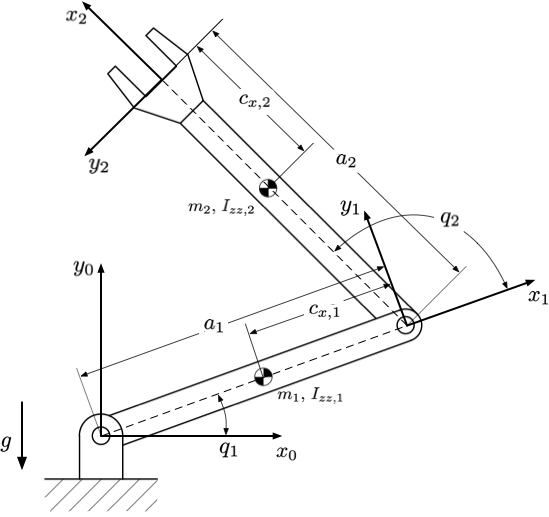

## Derivation

First, we define the DH table of the maniuplator. For the input to this toolbox, DH table must be defined as a $n\times 6%$ double matrix:


$$\text{DH} = \left[\matrix{
a_1 & \alpha_1 & d_1 & \theta_1 & t_1 & s_1 \cr
\vdots &\vdots &\vdots &\vdots &\vdots &\vdots \cr
a_n & \alpha_n & d_n & \theta_n & t_n & s_n \cr
 }\right]$$


where $a_i, \alpha_i, d_i$ and $\theta_i$ are the normal DH parameters, $t_i$ indicates the joint type (0 for revolute, 1 for prismatic) and $s_i$ is either a 1 or a -1, and indicates the direction of the joint. Internally, they are combined to make the DH table:


$$\left|
\matrix{
\text{Link Length } a_i & \text{Link twist } \alpha_i & \text{Link offset} d_i & \text{Joint angle } \theta_i \cr
a_i & \alpha_i & d_i + t_i s_i q_i & \theta_i + (1-t_i)s_i q_i
}
\right|$$


DH = [2.1   0	0     0   0   1;
      1.1   0	0     0   0   1];

We also need a gravity vector. This is a unit vector and is scaled by the gravitational constant internally. Here, gravity is pointing in the negative y direction.

g = [0; 1; 0];

Finally, we (optionally) need to define a vector of inertial parameters of the robot, $X$. This is **not** needed to run the derivation. But, it can be used to specify certain parameters as being zero. Internally, any parameter which is identically zero in the given $X$ matrix is assumed negligible and is not included in the derivation, leading to simpler results.

$X$ is defined as the concatenation of all the inertial parameters:


$$X = \left[
\matrix{
m_1 & r_{x,1} & r_{y,1} & r_{z,1} & I_{xx,1}& I_{yy,1}& I_{zz,1}& I_{xy,1}& I_{xz,1}& I_{yz,1} \cr
\vdots & \vdots & \vdots & \vdots & \vdots & \vdots & \vdots & \vdots & \vdots & \vdots \cr
m_n & r_{x,n} & r_{y,n} & r_{z,n} & I_{xx,n}& I_{yy,n}& I_{zz,n}& I_{xy,n}& I_{xz,n}& I_{yz,n}
}
\right]$$


Here, we assume the center of gravities are inline with the linkages, and that all but the $I_{zz}$ component of the inertias are negligible.

X = [1 -1 0 0 0 0 0.5 0 0 0;
     2 -1 0 0 0 0 0.3 0 0 0];

We can also specify the tolerance (default is 1e-11) and verbosity (default is true).

tolerance = [];
verbosity = true;

Now, we can run the derivation

[E, P] = PSDM.deriveModel(DH, g, X, tolerance, verbosity);


Running gravity derivation (9 search terms).
		9 terms reduced to 3, Took 0.31 seconds.
		Max Reprojection Error: 1.42e-14.
		Reduced from (3 / 3) to 2 parameters (took 0.00988 seconds).
		Reprojection error is 1.42e-14
	Gravity matching done. 2 terms remaining (took 0.369 sec total).


Running accel derivation (50 search terms).

	Searching in joint 1 (25 terms)...
		25 terms reduced to 2, Took 0.00 seconds.
		Max Reprojection Error: 6.75e-14.
		Reduced from (2 / 2) to 3 parameters (took 0.00654 seconds).
		Reprojection error is 1.42e-14
	Searching in joint 2 (25 terms)...
		25 terms reduced to 2, Took 0.00 seconds.
		Max Reprojection Error: 4.44e-16.
		Reduced from (2 / 2) to 2 parameters (took 0.00973 seconds).
		Reprojection error is 7.11e-15
	Combining terms:
		Reduced from (4 / 5) to 3 parameters (took 0.0059 seconds).
		Reprojection error is 1.42e-14
	Accel matching done. 3 terms remaining (took 0.0341 sec total).


Running centripital derivation (6 search terms).

	Searching i

E is the exponent matrix which represents the terms of the final result. P is a page array of the two reduction matrices for each joint. Because this is a simple example, we can inspect them:

disp(E)

   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0
   0   1   0   0   0   0   0   0   0   0
   0   1   0   0   0   0   0   1   1   1
   1   0   1   0   0   0   0   0   0   0
   0   0   1   0   1   0   1   0   0   0
   0   0   0   0   0   0   0   2   0   1
   0   0   0   0   0   0   0   0   2   1
   0   0   0   1   1   0   0   0   0   0
   0   0   0   0   0   1   1   0   0   0


disp(P)

(:,:,1) =
            1            0            0            0
            0      0.10533            0            0
            0     -0.10533            0            0
            0            0            1            0
            0    -0.045112            0            0
            0            0            0      0.11111
            0    -0.022556            0            0
            0            0            0            0
            0     0.022556            0            0
            0     0.045112            0            0
(:,:,2) =
            0            0            0            0
            0      0.10533            0            0
            0     -0.10533            0            0
            0            0            0      0.11111
            0    -0.022556            0            0
            0            0            0      0.11111
            0            0            0            0
            0    -0.022556            0            0
            0            0

## Testing

The PSDM model, defined by E and P, can be used either through full knowledge of $X$, the inertial parameters, or through experimental determination of the $\Theta$ regression parameters.

Here, since we do not have experimental data, we can just use the $X$ parameters above to validate the result. Note, this validation has actually already been performed in the derivation above – this is just to illustrate.

First, use the X2Theta function to convert the X matrix into the appropriate regression vector.

Theta = PSDM.X2Theta(DH, X, g, E, P);

Now, define some random poses.

N = 5;
DOF = 2;
Q = (rand(DOF, N)-0.5) * (2*pi);
Qd = (rand(DOF, N)-0.5);
Qdd = (rand(DOF, N)-0.5);

We can use the newton-euler algorithm to get the inverse dynamics.

tau_rne = PSDM.inverseDynamicsNewton(DH, X, Q, Qd, Qdd, 2, g)

tau_rne =       -46.286      -49.603      -20.681       37.988       24.738
     0.051373       1.9853       1.3539        1.597    -0.086535


Then use the PSDM model, and check the error:

tau_psdm = PSDM.inverseDynamics(E, P, Theta, Q, Qd, Qdd)

tau_psdm =       -46.286      -49.603      -20.681       37.988       24.738
     0.051373       1.9853       1.3539        1.597    -0.086535


fprintf('Max inverse dynamics error: %.5g\n', max(abs(tau_rne - tau_psdm), [], 'all'));

Max inverse dynamics error: 1.4211e-14


We can also validate the forward dynamic model by ensuring that we get the same joint accelerations we started with.

Qdd_psdm = PSDM.forwardDynamics(E, P, Theta, Q, Qd, tau_psdm)

Qdd_psdm =       0.48228    -0.089188      0.45949      0.48957      0.34703
    -0.027829      0.23447     -0.36436     -0.24352      0.13439


fprintf('Max forward dynamics error: %.5g\n', max(abs(Qdd_psdm - Qdd), [], 'all'));

Max forward dynamics error: 3.8858e-16


The errors should be negligible (machine precision levels).

## Faster real time code

The default PSDM functions for inverse and forward dynamics are a bit slow since there is some pre-processing to be done at each step, and complex indexing which is slow for matlab.

However, because the model is quite nicely organized in E and P, we can procedurally create matlab functions which are much faster than the default functions, specifically for a given $\{E, P, \Theta\}$ tuple.

Add the temp directory and define some filenames for the functions:

addpath(fullfile(utilities.PSDMDir, 'temp'));
filename_inverse = fullfile( utilities.PSDMDir, 'temp', 'PSDM_inverseDynamics_twolink.m');
filename_forward = fullfile( utilities.PSDMDir, 'temp', 'PSDM_forwardDynamics_twolink.m');

Can decide if you want to mex-compile your code or not, as well as whether or not to leverage parallel computing (requires the parallel computing toolbox). Note, MEX compilation can take some time on more complex models.

doMex = true; % Whether or not to mex result for speed
doPar = true; % Whether to evaluate states in parallel

Now, derive functions

PSDM.makeInverseDynamics(filename_inverse, E, P, Theta, ...
   'do_mex', doMex, 'parallel', doPar);

Compiling into mex file... Code generation successful: View report
 Done!


PSDM.makeForwardDynamics(filename_forward, E, P, Theta, ...
   'do_mex', doMex, 'parallel', doPar);

Compiling into mex file... Code generation successful: View report
 Done!


## Test Evaluation Speed

The code below generations a large number of sample poses and checks the evaluation speed of the forward and inverse dynamics functions.

% Generate samples
N = 10e5;
DOF = 2;
Q = (rand(DOF, N)-0.5) * (2*pi);
Qd = (rand(DOF, N)-0.5) * (10);
Qdd = (rand(DOF, N)-0.5) * (50);

tic1 = tic;
tau_psdm = PSDM.inverseDynamics(E, P, Theta, Q, Qd, Qdd);
t1 = toc(tic1);

fprintf("Default inverse dynamics function took %.3g seconds per state.\n", t1/N);

Default inverse dynamics function took 5.1e-07 seconds per state.



% Run test. We run the function once first since matlab doesn't run
% functions very quickly the first time.
A = PSDM_forwardDynamics_twolink_mex(Q(:, 1), Qd(:, 1), Qdd(:, 1));
tic2 = tic;
tau_psdm_opt = PSDM_inverseDynamics_twolink_mex(Q, Qd, Qdd);
t2 = toc(tic2);

fprintf("Optimized inverse dynamics function took %.3g seconds per state.\n", t2/N);

Optimized inverse dynamics function took 3.04e-07 seconds per state.



fprintf("Maximum error: %.5g\n", max(abs(tau_psdm - tau_psdm_opt), [], 'all'));

Maximum error: 2.2737e-13



tic3 = tic;
Qdd_psdm = PSDM.forwardDynamics(E, P, Theta, Q, Qd, tau_psdm);
t3 = toc(tic3);

fprintf("Default forward dynamics function took %.3g seconds per state.\n", t3/N);

Default forward dynamics function took 4.31e-06 seconds per state.



% Run test. We run the function once first since matlab doesn't run
% functions very quickly the first time.
A = PSDM_forwardDynamics_twolink_mex(Q(:, 1), Qd(:, 1), tau_psdm(:, 1));
tic4 = tic;
Qdd_psdm_opt = PSDM_forwardDynamics_twolink_mex(Q, Qd, tau_psdm);
t4 = toc(tic4);

fprintf("Optimized forward dynamics function took %.3g seconds per state.\n", t4/N);

Optimized forward dynamics function took 1.55e-07 seconds per state.



fprintf("Maximum error: %.5g\n", max(abs(Qdd_psdm - Qdd_psdm_opt), [], 'all'));

Maximum error: 9.9476e-14
